%%a)3
p = 0.3; %chance
k = 3; %n de acontecimentos
n = 5; %repeticoes
prob3= nchoosek(n,k)*p^k*(1-p)^(n-k); % nchoosek(n,k)= n!/(n-k)!/k!

disp(prob3)

    0.1323



%%b)2 ou 1
p = 0.3; %chance
k = 1; %n de acontecimentos
n = 5; %repeticoes
prob1= nchoosek(n,k)*p^k*(1-p)^(n-k); % nchoosek(n,k)= n!/(n-k)!/k!

k = 2; %n de acontecimentos
prob2= nchoosek(n,k)*p^k*(1-p)^(n-k); % nchoosek(n,k)= n!/(n-k)!/k!

disp(prob1+prob2)

    0.6688



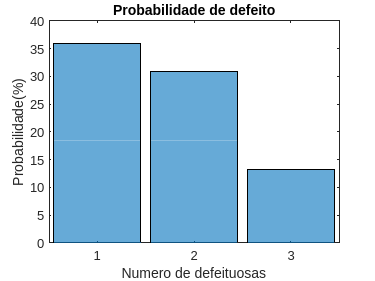

probs = [prob1, prob2, prob3];
probs = probs.*100;

categorias = {'1', '2', '3'};

histogram('Categories', categorias, 'BinCounts', probs)
xlabel('Numero de defeituosas')
ylabel('Probabilidade(%)')
title('Probabilidade de defeito')